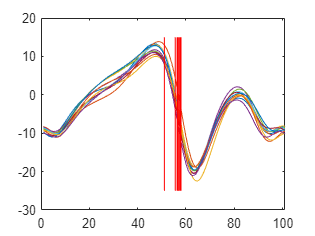

% clc;
% close;
% clear;
% 
% load('analysis.mat');
% load('contact_data.mat');
% load('footOff_indices.mat');
% load('intervals.mat');
% 
% plot(analysis.light.RT.AnkleDorsiflexion);
% hold on;
% 
% normalizedContactPoints=[];

function 

for i = 1:size(intervals, 1) - 1
    % Get the contact points within the current interval
    intervalContactPoints = footOff_indices(footOff_indices >= intervals(i, 1) & footOff_indices <= intervals(i, 2));
    
    % Normalize the contact points within the current interval
    normalizedIntervalContactPoints = (intervalContactPoints - intervals(i, 1)) / (intervals(i, 2) - intervals(i, 1)) * 100;
    
    % Append the normalized contact points to the overall list
    normalizedContactPoints = [normalizedContactPoints; normalizedIntervalContactPoints];
end

for i = 1:length(normalizedContactPoints)
        line([normalizedContactPoints(i) normalizedContactPoints(i)], ylim, 'Color', 'r');
end